Script saves to `'/checkpoints'` directory.

Copy the best results to `'/results'` directory for post processing and showcasing.

addpath('results', 'results/models', ...
        'Data', ...
        'lib', 'lib/utils')

# Model Showcase

## Histograms of Relative Frequencies for Error Metrics on Trainset Splits

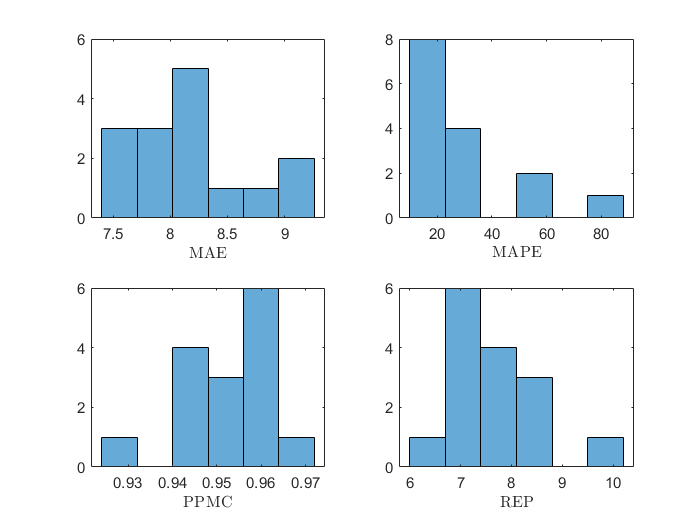

load('metrics.mat')

nbins = 6;

fig_err_metrics_train = figure(1);
subplot(221); histogram(MAE, nbins)
xlabel('MAE', 'Interpreter', 'latex')
subplot(222); histogram(MAPE, nbins)
xlabel('MAPE', 'Interpreter', 'latex')
subplot(223); histogram(PPMC, nbins)
xlabel('PPMC', 'Interpreter', 'latex')
subplot(224); histogram(REP, nbins)
xlabel('REP', 'Interpreter', 'latex')
exportgraphics(fig_err_metrics_train,'figures/trainset_error_metrics_hist.png','Resolution',300)

## Performance Assesment

### Chosing Best Model

Criteria to choose best model based on minimising MAE, MAPE and REP while maximising the PPMC.

Matrix is constructed for each error metrics evaluated in `'main.m'` and is saved in `'decision_matrix.xlsx'`. Selected best model is `'model14.mat'`.

load('FinalTest.mat')

n = size(Finaltest, 1);                 % number of samples
X_real = Finaltest(:, setdiff(1:end, 35));   % input features
y_real = Finaltest(:, 35);                   % target feature


% load models ---------------------------------------------
n_models = 15;

MAE_final = zeros(n_models, 1);
MAPE_final = zeros(n_models, 1);
REP_final = zeros(n_models, 1);
PPMC_final = zeros(n_models, 1);

layers = cell(n_models, 1); 
W = cell(n_models, 1);
y_predict = cell(n_models, 1);
for mdl = 1:n_models
    layers{mdl} = load(sprintf("model%i", mdl)).layers_best;
    W{mdl} = load(sprintf("model%i", mdl)).W_opt;

    Xtest = normalize(X_real, "range");
    [ytest, y_centerValue, y_scaleValue] = normalize(y_real, "range");
    y_predict{mdl} = predict(Xtest, W{mdl}, "sigmoid", layers{mdl}) ...
            .* y_scaleValue + y_centerValue;

    MAE_final(mdl) = mae(y_real, y_predict{mdl});
    MAPE_final(mdl) = mape(y_real, y_predict{mdl});
    REP_final(mdl) = rep(y_real, y_predict{mdl});
    PPMC_final(mdl) = corr(y_real, y_predict{mdl});
end

## Histograms of Relative Frequencies for Error Metrics on Finaltest Splits

Chosen best model is model 14.

best_mdl = 14;
n_samples = 100;

MAE_final = zeros(n_samples, 1);
MAPE_final = zeros(n_samples, 1);
REP_final = zeros(n_samples, 1);
PPMC_final = zeros(n_samples, 1);
inds = crossvalind('Kfold', n, n_samples);  % split up data
for k = 1:n_samples
    % train-test split
    Xtest = X_real(inds==k, :);
    ytest = y_real(inds==k, :);

    Xtest = normalize(Xtest, "range");
    [~, y_centerValue, y_scaleValue] = normalize(ytest, "range");
    y_hat = predict(Xtest, W{best_mdl}, "sigmoid", layers{best_mdl}) ...
            .* y_scaleValue + y_centerValue;

    MAE_final(k) = mae(ytest, y_hat);
    MAPE_final(k) = mape(ytest, y_hat);
    REP_final(k) = rep(ytest, y_hat);
    PPMC_final(k) = corr(ytest, y_hat);
end

Plotting Histograms

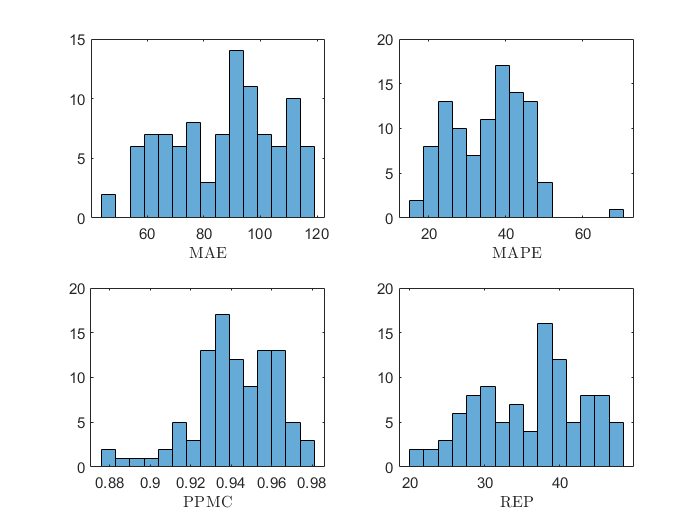

load('metrics.mat')

nbins = 15;

fig_err_metrics_final = figure(2);
subplot(221); histogram(MAE_final, nbins)
xlabel('MAE', 'Interpreter', 'latex')
subplot(222); histogram(MAPE_final, nbins)
xlabel('MAPE', 'Interpreter', 'latex')
subplot(223); histogram(PPMC_final, nbins)
xlabel('PPMC', 'Interpreter', 'latex')
subplot(224); histogram(REP_final, nbins)
xlabel('REP', 'Interpreter', 'latex')
exportgraphics(fig_err_metrics_final,'figures/finalset_error_metrics_hist.png','Resolution',300)

## Plot of Real vs Predicted Target Feature on Unseen Data

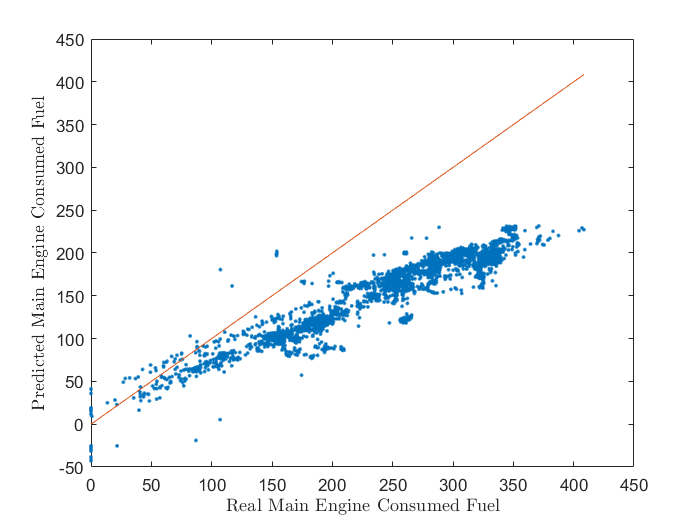

fig_real_vs_predict = figure(3);
plot(y_real, y_predict{14}, '.');
hold on
plot(y_real, y_real);
hold off
xlabel('Real Main Engine Consumed Fuel', 'Interpreter', 'latex')
ylabel('Predicted Main Engine Consumed Fuel', 'Interpreter', 'latex')
exportgraphics(fig_real_vs_predict,'figures/real_vs_predict.png','Resolution',300)